clear,clc,close all
import_data_2025MCM_C
medalAmountForSports = readtable("Sport_medal_people2.xlsx");
people2028 = readtable("people2028.xlsx");

tic
never_medal_ind = zeros(3,1);
err_ind = zeros(2,1);
kmedal = 0;
kerr = 0;
knormal = 0;
ktolowevents1 = 0;
ktolowevents2 = 0;
sumallsportimportant1 = struct();
sumallsportimportant2 = struct();
firsttwosport = ["" "" ""; "" "" ""];
predicttable = table();
for n = 1:length(NOC2Country)
    country_temp = NOC2Country(n,1);
    data = medalAmountForSports(string(medalAmountForSports.NOC) == country_temp,:);
    m = max(data.TotalMedalCount);
    data.TotalMedalCount = data.TotalMedalCount/m;
    NumObs = height(data);
    % Reset the random stream state, for reproducibility
    % Comment this line out to generate different data partitions each time the example is run
    rng('default');
    if height(data)<=6
        ktolowevents1 = ktolowevents1 + 1;
        disp(NOC2Country(n,2) + '参加过的项目太少,1')
        continue
    end
    % try
        c = cvpartition(NumObs,'HoldOut',0.4);
        TrainingInd = training(c);
        TestInd = test(c);

        if all(isnan((data.TotalMedalCount)))
            kmedal = kmedal + 1;
            never_medal_ind(kmedal) = n;
            data.TotalMedalCount = zeros(height(data),1);
            % n
            continue
        end

        mdlTobit = fitLGDModel(data(TrainingInd,:),'tobit','CensoringSide','both','PredictorVars',{'sumofpeople' 'Year' 'Sport'},'ResponseVar','TotalMedalCount');
        
        dataTotalMedalCountPredicted = table;
        dataTotalMedalCountPredicted.Observed = data.TotalMedalCount(TestInd) * m;

        dataTotalMedalCountPredicted.Tobit = predict(mdlTobit,data(TestInd,:)) * m;
        % disp((dataTotalMedalCountPredicted))

        [~,ind] = sort(mdlTobit.UnderlyingModel.Coefficients.Estimate,'descend');
        % 
        % for m = 1:length(ind)
        %     mdlTobit.UnderlyingModel.CoefficientNames{ind(m)}
        % end
        
        % temp = []

        
        % 判断运动的重要性
        temp = mdlTobit.UnderlyingModel.CoefficientNames;
        if length(temp) <=5
            ktolowevents2 = ktolowevents2 + 1;

            disp(NOC2Country(n,2) + '参加过的项目太少,2')
            continue
        end

        s = [string(temp{ind(1)}),string(temp{ind(2)})];
        indtemp = 2;
        for chachong = 1:4
        while contains("sumofpeople",s)
            for m_temp = 1:2
                if s(m_temp) == "sumofpeople"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("Year",s)
            for m_temp = 1:2
                if s(m_temp) == "Year"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("(Intercept)",s)
            for m_temp = 1:2
                if s(m_temp) == "(Intercept)"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("(Sigma)",s)
            for m_temp = 1:2
                if s(m_temp) == "(Sigma)"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        end
        
        knormal = knormal + 1;
        firsttwosport(knormal,:) = [NOC2Country(n,2) s];
        tc1 = char(s(1));
        tc1(tc1==' ') = '_';
        tc1(tc1=='/') = '_';
        ts1 = string(tc1);

        tc2 = char(s(2));
        tc2(tc2==' ') = '_';
        tc2(tc2=='/') = '_';
        ts2 = string(tc2);        
        if ismember(tc1,fieldnames(sumallsportimportant1))
            eval("sumallsportimportant1."+ts1+" =  sumallsportimportant1."+ts1+" + 1;");
        else
            eval("sumallsportimportant1."+ts1+" = 1;");
        end
        if ismember(tc2,fieldnames(sumallsportimportant2))
            eval("sumallsportimportant2."+ts2+" =  sumallsportimportant2."+ts2+" + 1;");
        else
            eval("sumallsportimportant2."+ts2+" = 1;");
        end

        %PREDICT 2028
        predict_2028 = people2028(people2028.NOC == country_temp,:);

        total = predict(mdlTobit,predict_2028) * m;
        total(isnan(total)) = 0;
        % sum(total)
        predicttable.NOC(knormal) = country_temp;
        predicttable.country(knormal) = NOC2Country(n,2);
        predicttable.TotalMedalCount(knormal) = sum(total);
        


    % catch ME
    %     kerr = kerr + 1;
    %     err_ind(kerr) = n;
    %     disp(['Iteration ', num2str(n), ': Failed with error - ', ME.message]);
    %     % 可以选择跳过当前迭代或执行其他错误处理逻辑
    % end
    % if mod(n,20) == 0
    %     n
    % end
end

North Yemen参加过的项目太少,1


Dominica参加过的项目太少,2


South Yemen参加过的项目太少,1


Refugee Olympic Athletes参加过的项目太少,1


Crete参加过的项目太少,1


Rhodesia参加过的项目太少,1


Circus参加过的项目太少,1


North Borneo参加过的项目太少,1


Unknown参加过的项目太少,1


Newfoundland参加过的项目太少,1


South Sudan参加过的项目太少,1


% never_medal_ind
toc

历时 25.098694 秒。


firsttwosport

firsttwosport = 155×3 string 数组
    "China"            "Sport_Table Tennis"        "Sport_Weightlifting"    
    "Denmark"          "Sport_Canoe"               "Sport_Badminton"        
    "Netherlands"      "Sport_Cycling"             "Sport_Basketball"       
    "Finland"          "Sport_Wrestling"           "Sport_Art Competitions" 
    "Norway"           "Sport_Figure Skating"      "Sport_Shooting"         
    "Romania"          "Sport_Gymnastics"          "Sport_Canoe"            
    "Estonia"          "Sport_Judo"                "Sport_Sailing"          
    "France"           "Sport_Croquet"             "Sport_Judo"             
    "Morocco"          "Sport_Athletics"           "Sport_Boxing"           
    "Spain"            "Sport_Basque Pelota"       "Sport_Polo"             
    "Egypt"            "Sport_Taekwondo"           "Sport_Modern Pentathlon"
    "Iran"             "Sport_Taekwondo"           "Sport_Weightlifting"    
    "Bulgaria"         "Sport_Karate"       

predicttable

predicttable = 155×3 table
     NOC        country       TotalMedalCount
    _____    _____________    _______________

    "CHN"    "China"                133.3    
    "DEN"    "Denmark"             9.2557    
    "NED"    "Netherlands"         33.316    
    "FIN"    "Finland"             3.7475    
    "NOR"    "Norway"              11.554    
    "ROU"    "Romania"             15.705    
    "EST"    "Estonia"            0.23988    
    "FRA"    "France"              41.035    
    "MAR"    "Morocco"             3.7037    
    "ESP"    "Spain"               29.931    
    "EGY"    "Egypt"               3.5199    
    "IRI"    "Iran"                7.0868    
    "BUL"    "Bulgaria"            16.553    
    "ITA"    "Italy"               46.178    
    "AZE"    "Azerbaijan"          9.5088    
    "SUD"    "Sudan"                    0    


% disp((dataTotalMedalCountPredicted))

% sumallsportimportant1
% sumallsportimportant2

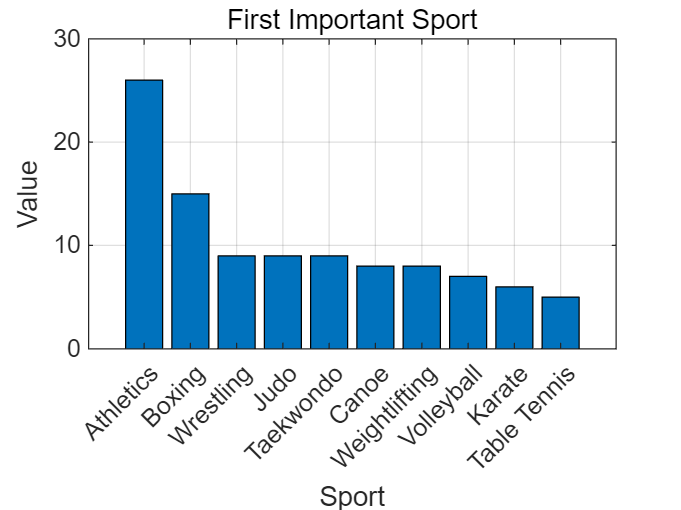

% 假设你的结构体名为 sumallsportimportant1
sports = string(fieldnames(sumallsportimportant1)); % 获取结构体字段名（运动项目）
values = struct2array(sumallsportimportant1); % 将结构体转换为数组（对应的数值）
[values,ind] = sort(values,'descend');
sports = sports(ind(1:10));
values = values(1:10);

for m = 1:length(sports)
    chartemp = char(sports(m));
    chartemp(chartemp=='_') = ' ';
    chartemp = chartemp(7:end);
    sports(m) = string(chartemp);
end
% 注意：struct2array 默认返回结构体中第一个字段的数组，如果所有字段都是相同大小的数值数组，这可以工作。
% 但如果结构体中有非数值字段或字段大小不一致，这种方法会出错。
% 在这个例子中，我们假设所有字段都是数值且大小相同（即只有一个数值）。
 
% 如果 struct2array 不适用（例如，如果结构体中有混合类型的数据），你需要手动提取数值：
% values = zeros(1, length(sports));
% for i = 1:length(sports)
%     values(i) = sumallsportimportant1.(sports{i});
% end
 
% 绘制条形图
figure; % 创建新图形窗口
bar(values); % 绘制条形图（默认 x 轴是索引）
 
% 设置 x 轴标签为运动项目名称
set(gca, 'XTickLabel', sports); % gca 获取当前轴句柄
% xstickrotation(45); % 旋转 x 轴标签，以便更好地显示长名称
 xtickangle(45);
% 设置图表标题和轴标签
title('First Important Sport');
xlabel('Sport');
ylabel('Value');
 
% 如果需要，还可以添加网格线、图例等
grid on;

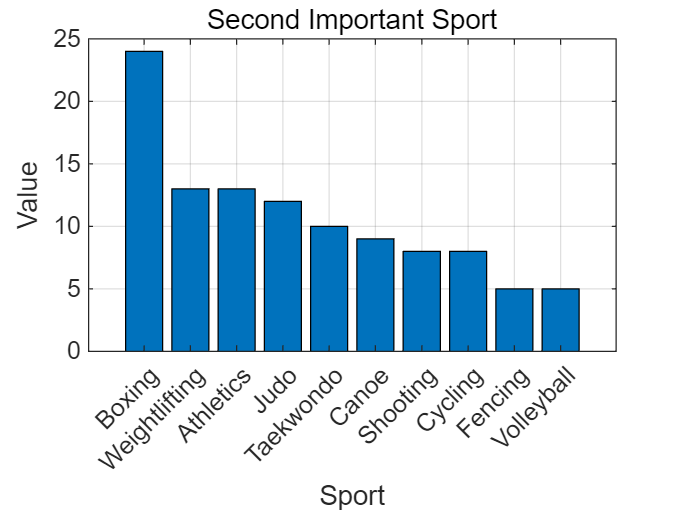

% 假设你的结构体名为 sumallsportimportant1
sports = string(fieldnames(sumallsportimportant2)); % 获取结构体字段名（运动项目）
values = struct2array(sumallsportimportant2); % 将结构体转换为数组（对应的数值）
[values,ind] = sort(values,'descend');
sports = sports(ind(1:10));
values = values(1:10);

for m = 1:length(sports)
    chartemp = char(sports(m));
    chartemp(chartemp=='_') = ' ';
    chartemp = chartemp(7:end);
    sports(m) = string(chartemp);
end


% 注意：struct2array 默认返回结构体中第一个字段的数组，如果所有字段都是相同大小的数值数组，这可以工作。
% 但如果结构体中有非数值字段或字段大小不一致，这种方法会出错。
% 在这个例子中，我们假设所有字段都是数值且大小相同（即只有一个数值）。
 
% 如果 struct2array 不适用（例如，如果结构体中有混合类型的数据），你需要手动提取数值：
% values = zeros(1, length(sports));
% for i = 1:length(sports)
%     values(i) = sumallsportimportant1.(sports{i});
% end
 
% 绘制条形图
figure; % 创建新图形窗口
bar(values); % 绘制条形图（默认 x 轴是索引）
 
% 设置 x 轴标签为运动项目名称
set(gca, 'XTickLabel', sports); % gca 获取当前轴句柄
% xstickrotation(45); % 旋转 x 轴标签，以便更好地显示长名称
 xtickangle(45);
% 设置图表标题和轴标签
title('Second Important Sport');
xlabel('Sport');
ylabel('Value');
 
% 如果需要，还可以添加网格线、图例等
grid on;



% people2028.Year = 2028 * ones(height(people2028),1)
% dataTotalMedalCountPredicted.Tobit = predict(mdlTobit,data(TestInd,:)); %%%预测用！！！

[~,ind] = sort(predicttable.TotalMedalCount,'descend');
predicttable = predicttable(ind,:)

predicttable = 155×3 table
     NOC         country        TotalMedalCount
    _____    _______________    _______________

    "GDR"    "East Germany"         358.62     
    "URS"    "Soviet Union"         212.47     
    "USA"    "United States"        141.79     
    "CHN"    "China"                 133.3     
    "FRG"    "West Germany"         129.48     
    "RUS"    "Russia"               88.196     
    "JPN"    "Japan"                58.496     
    "AUS"    "Australia"            53.434     
    "GER"    "Germany"              52.525     
    "BRA"    "Brazil"               48.352     
    "ITA"    "Italy"                46.178     
    "GBR"    "Great Britain"        44.729     
    "FRA"    "France"               41.035     
    "EUN"    "Unified Team"         41.001     
    "ROC"    "Russia"               37.005     
    "NED"    "Netherlands"          33.316     


% ind_change = [1 2 5 14 22 85 112 117 139]


% predicttable(1:155~=ind_change,:)
% predicttable([3,4,6:13],:)

medallist2024 = medal_counts(medal_counts.Year==2024,:)

medallist2024 = 91×7 table
    Rank           NOC           Gold    Silver    Bronze    Total    Year
    ____    _________________    ____    ______    ______    _____    ____

      1     {'United States'}     40       44        42       126     2024
      2     {'China'        }     40       27        24        91     2024
      3     {'Japan'        }     20       12        13        45     2024
      4     {'Australia'    }     18       19        16        53     2024
      5     {'France'       }     16       26        22        64     2024
      6     {'Netherlands'  }     15        7        12        34     2024
      7     {'Great Britain'}     14       22        29        65     2024
      8     {'South Korea'  }     13        9        10        32     2024
      9     {'Italy'        }     12       13        15        40     2024
     10     {'Germany'      }     12       13         8        33     2024
     11     {'New Zealand'  }     10        7         3        20     20

for m = 1:height(medallist2024)
    countrytemp = string(medallist2024.NOC{m});
    temptemp = predicttable(predicttable.country == countrytemp,:);
    if ~isempty(temptemp)
    if temptemp.TotalMedalCount - medallist2024{m,6}<0 && abs(temptemp.TotalMedalCount - medallist2024{m,6})>6
        disp(countrytemp+' will do worse in 2028, decrease is '+num2str(temptemp.TotalMedalCount - medallist2024{m,6}))
    elseif temptemp.TotalMedalCount - medallist2024{m,6}>0 && abs(temptemp.TotalMedalCount - medallist2024{m,6})>6
        disp(countrytemp+' will do better in 2028, increase is '+num2str(temptemp.TotalMedalCount - medallist2024{m,6}))
    end
    end
    
end

United States will do better in 2028, increase is 15.792
China will do better in 2028, increase is 42.2994
Japan will do better in 2028, increase is 13.4957


France will do worse in 2028, decrease is -22.9648
Great Britain will do worse in 2028, decrease is -20.2709


Italy will do better in 2028, increase is 6.1783
Germany will do better in 2028, increase is 19.5249


Canada will do worse in 2028, decrease is -6.2955


Spain will do better in 2028, increase is 11.9306
Brazil will do better in 2028, increase is 28.352
Romania will do better in 2028, increase is 6.7054
Bulgaria will do better in 2028, increase is 9.5526
Serbia will do better in 2028, increase is 10.2733
Czech Republic will do better in 2028, increase is 8.4135
Cuba will do better in 2028, increase is 6.2577
Bahrain will do better in 2028, increase is 8.2547
Poland will do better in 2028, increase is 12.6535
North Korea will do better in 2028, increase is 12.5606
Peru will do better in 2028, increase is 8.9271


% sensitivity analysis


tic
never_medal_ind = zeros(3,1);
err_ind = zeros(2,1);
kmedal = 0;
kerr = 0;
knormal = 0;
ktolowevents1 = 0;
ktolowevents2 = 0;
sumallsportimportant1 = struct();
sumallsportimportant2 = struct();
firsttwosport = ["" "" ""; "" "" ""];
predicttable = table();
predicttable_sensitivity = table();
predicttable_sensitivity_plus10 = table();
predicttable_sensitivity_minus10 = table();
for n = 1:length(NOC2Country)
    country_temp = NOC2Country(n,1);
    data = medalAmountForSports(string(medalAmountForSports.NOC) == country_temp,:);
    m = max(data.TotalMedalCount);
    data.TotalMedalCount = data.TotalMedalCount/m;
    NumObs = height(data);
    % Reset the random stream state, for reproducibility
    % Comment this line out to generate different data partitions each time the example is run
    rng('default');
    if height(data)<=6
        ktolowevents1 = ktolowevents1 + 1;
        disp(NOC2Country(n,2) + '参加过的项目太少,1')
        continue
    end
    % try
        c = cvpartition(NumObs,'HoldOut',0.4);
        TrainingInd = training(c);
        TestInd = test(c);

        if all(isnan((data.TotalMedalCount)))
            kmedal = kmedal + 1;
            never_medal_ind(kmedal) = n;
            data.TotalMedalCount = zeros(height(data),1);
            % n
            continue
        end

        mdlTobit = fitLGDModel(data(TrainingInd,:),'tobit','CensoringSide','both','PredictorVars',{'sumofpeople' 'Year' 'Sport'},'ResponseVar','TotalMedalCount');
        
        dataTotalMedalCountPredicted = table;
        dataTotalMedalCountPredicted.Observed = data.TotalMedalCount(TestInd) * m;

        dataTotalMedalCountPredicted.Tobit = predict(mdlTobit,data(TestInd,:)) * m;
        % disp((dataTotalMedalCountPredicted))

        [~,ind] = sort(mdlTobit.UnderlyingModel.Coefficients.Estimate,'descend');
        % 
        % for m = 1:length(ind)
        %     mdlTobit.UnderlyingModel.CoefficientNames{ind(m)}
        % end
        
        % temp = []

        
        % 判断运动的重要性
        temp = mdlTobit.UnderlyingModel.CoefficientNames;
        if length(temp) <=5
            ktolowevents2 = ktolowevents2 + 1;

            disp(NOC2Country(n,2) + '参加过的项目太少,2')
            continue
        end

        s = [string(temp{ind(1)}),string(temp{ind(2)})];
        indtemp = 2;
        for chachong = 1:4
        while contains("sumofpeople",s)
            for m_temp = 1:2
                if s(m_temp) == "sumofpeople"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("Year",s)
            for m_temp = 1:2
                if s(m_temp) == "Year"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("(Intercept)",s)
            for m_temp = 1:2
                if s(m_temp) == "(Intercept)"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        while contains("(Sigma)",s)
            for m_temp = 1:2
                if s(m_temp) == "(Sigma)"
                    indtemp = indtemp + 1;
                    s = [s([1 2]~=m_temp) ,string(temp{ind(indtemp)})];
                    break
                end
            end
        end
        end
        
        knormal = knormal + 1;
        firsttwosport(knormal,:) = [NOC2Country(n,2) s];
        tc1 = char(s(1));
        tc1(tc1==' ') = '_';
        tc1(tc1=='/') = '_';
        ts1 = string(tc1);

        tc2 = char(s(2));
        tc2(tc2==' ') = '_';
        tc2(tc2=='/') = '_';
        ts2 = string(tc2);        
        if ismember(tc1,fieldnames(sumallsportimportant1))
            eval("sumallsportimportant1."+ts1+" =  sumallsportimportant1."+ts1+" + 1;");
        else
            eval("sumallsportimportant1."+ts1+" = 1;");
        end
        if ismember(tc2,fieldnames(sumallsportimportant2))
            eval("sumallsportimportant2."+ts2+" =  sumallsportimportant2."+ts2+" + 1;");
        else
            eval("sumallsportimportant2."+ts2+" = 1;");
        end

        %PREDICT 2028
        predict_2028 = people2028(people2028.NOC == country_temp,:);
        
        total = predict(mdlTobit,predict_2028) * m;
        total(isnan(total)) = 0;
        % sum(total)
        predicttable.NOC(knormal) = country_temp;
        predicttable.country(knormal) = NOC2Country(n,2);
        predicttable.TotalMedalCount(knormal) = sum(total);

        predict_2028_nosie = predict_2028;
        predict_2028_nosie.sumofpeople = predict_2028_nosie.sumofpeople * (1 + (rand()-0.5)/5);

        total_nosie = predict(mdlTobit,predict_2028_nosie) * m;
        total_nosie(isnan(total_nosie)) = 0;
        % sum(total)
        predicttable_sensitivity.NOC(knormal) = country_temp;
        predicttable_sensitivity.country(knormal) = NOC2Country(n,2);
        predicttable_sensitivity.TotalMedalCount(knormal) = sum(total_nosie);

        predict_2028_nosie_plus10 = predict_2028;
        predict_2028_nosie_plus10.sumofpeople = predict_2028_nosie_plus10.sumofpeople * 1.1;

        total_nosie = predict(mdlTobit,predict_2028_nosie_plus10) * m;
        total_nosie(isnan(total_nosie)) = 0;
        % sum(total)
        predicttable_sensitivity_plus10.NOC(knormal) = country_temp;
        predicttable_sensitivity_plus10.country(knormal) = NOC2Country(n,2);
        predicttable_sensitivity_plus10.TotalMedalCount(knormal) = sum(total_nosie);

        predict_2028_nosie_minus10 = predict_2028;
        predict_2028_nosie_minus10.sumofpeople = predict_2028_nosie_minus10.sumofpeople * 0.9;

        total_nosie = predict(mdlTobit,predict_2028_nosie_minus10) * m;
        total_nosie(isnan(total_nosie)) = 0;
        % sum(total)
        predicttable_sensitivity_minus10.NOC(knormal) = country_temp;
        predicttable_sensitivity_minus10.country(knormal) = NOC2Country(n,2);
        predicttable_sensitivity_minus10.TotalMedalCount(knormal) = sum(total_nosie);
        


    % catch ME
    %     kerr = kerr + 1;
    %     err_ind(kerr) = n;
    %     disp(['Iteration ', num2str(n), ': Failed with error - ', ME.message]);
    %     % 可以选择跳过当前迭代或执行其他错误处理逻辑
    % end
    % if mod(n,20) == 0
    %     n
    % end
end

North Yemen参加过的项目太少,1


Dominica参加过的项目太少,2


South Yemen参加过的项目太少,1


Refugee Olympic Athletes参加过的项目太少,1


Crete参加过的项目太少,1


Rhodesia参加过的项目太少,1


Circus参加过的项目太少,1


North Borneo参加过的项目太少,1


Unknown参加过的项目太少,1


Newfoundland参加过的项目太少,1


South Sudan参加过的项目太少,1


predicttable

predicttable = 155×3 table
     NOC        country       TotalMedalCount
    _____    _____________    _______________

    "CHN"    "China"                133.3    
    "DEN"    "Denmark"             9.2557    
    "NED"    "Netherlands"         33.316    
    "FIN"    "Finland"             3.7475    
    "NOR"    "Norway"              11.554    
    "ROU"    "Romania"             15.705    
    "EST"    "Estonia"            0.23988    
    "FRA"    "France"              41.035    
    "MAR"    "Morocco"             3.7037    
    "ESP"    "Spain"               29.931    
    "EGY"    "Egypt"               3.5199    
    "IRI"    "Iran"                7.0868    
    "BUL"    "Bulgaria"            16.553    
    "ITA"    "Italy"               46.178    
    "AZE"    "Azerbaijan"          9.5088    
    "SUD"    "Sudan"                    0    


predicttable_sensitivity

predicttable_sensitivity = 155×3 table
     NOC        country       TotalMedalCount
    _____    _____________    _______________

    "CHN"    "China"                142.9    
    "DEN"    "Denmark"             9.4547    
    "NED"    "Netherlands"         30.296    
    "FIN"    "Finland"             3.2942    
    "NOR"    "Norway"              10.227    
    "ROU"    "Romania"             15.189    
    "EST"    "Estonia"            0.22657    
    "FRA"    "France"              40.717    
    "MAR"    "Morocco"             3.7348    
    "ESP"    "Spain"               32.985    
    "EGY"    "Egypt"               4.4032    
    "IRI"    "Iran"                 7.071    
    "BUL"    "Bulgaria"            18.126    
    "ITA"    "Italy"               43.004    
    "AZE"    "Azerbaijan"          8.4666    
    "SUD"    "Sudan"                    0    


predicttable_sensitivity_plus10

predicttable_sensitivity_plus10 = 155×3 table
     NOC        country       TotalMedalCount
    _____    _____________    _______________

    "CHN"    "China"               145.17    
    "DEN"    "Denmark"             10.472    
    "NED"    "Netherlands"          37.32    
    "FIN"    "Finland"             4.2961    
    "NOR"    "Norway"              13.223    
    "ROU"    "Romania"             17.295    
    "EST"    "Estonia"            0.26015    
    "FRA"    "France"               43.85    
    "MAR"    "Morocco"             3.7452    
    "ESP"    "Spain"               33.703    
    "EGY"    "Egypt"                4.426    
    "IRI"    "Iran"                7.8263    
    "BUL"    "Bulgaria"            18.166    
    "ITA"    "Italy"               50.396    
    "AZE"    "Azerbaijan"          10.753    
    "SUD"    "Sudan"                    0    


predicttable_sensitivity_minus10

predicttable_sensitivity_minus10 = 155×3 table
     NOC        country       TotalMedalCount
    _____    _____________    _______________

    "CHN"    "China"               121.68    
    "DEN"    "Denmark"              8.123    
    "NED"    "Netherlands"         29.488    
    "FIN"    "Finland"             3.2433    
    "NOR"    "Norway"              9.9689    
    "ROU"    "Romania"             14.168    
    "EST"    "Estonia"            0.22134    
    "FRA"    "France"              38.319    
    "MAR"    "Morocco"             3.6576    
    "ESP"    "Spain"               26.326    
    "EGY"    "Egypt"                2.727    
    "IRI"    "Iran"                6.3602    
    "BUL"    "Bulgaria"            15.072    
    "ITA"    "Italy"               42.018    
    "AZE"    "Azerbaijan"          8.2822    
    "SUD"    "Sudan"                    0    


predict_sensitive = table();
predict_sensitive.NOC = predicttable.NOC;
predict_sensitive.country = predicttable.country;
predict_sensitive.Predict = predicttable.TotalMedalCount;
predict_sensitive.sensitivity = predicttable_sensitivity.TotalMedalCount;
predict_sensitive.sensitivity_plus10 = predicttable_sensitivity_plus10.TotalMedalCount;
predict_sensitive.sensitivity_minus10 = predicttable_sensitivity_minus10.TotalMedalCount;
df1 = abs(predict_sensitive.Predict - predict_sensitive.sensitivity)./predict_sensitive.Predict;
df2 = abs(predict_sensitive.Predict - predict_sensitive.sensitivity_plus10)./predict_sensitive.Predict;
df3 = abs(predict_sensitive.Predict - predict_sensitive.sensitivity_minus10)./predict_sensitive.Predict;
predict_sensitive.relerr_sensitive = df1;
predict_sensitive.relerr_sensitive_plus10 = df2;
predict_sensitive.relerr_sensitive_minus10 = df3;

sum(df1(~isnan(df1) & ~isinf(df1)))

ans = 17.5409

sum(df2(~isnan(df2) & ~isinf(df2)))

ans = 1.6647e+03

sum(df3(~isnan(df3) & ~isinf(df3)))

ans = 26.8345


ddf1 = abs(predict_sensitive.Predict - predict_sensitive.sensitivity);
ddf2 = abs(predict_sensitive.Predict - predict_sensitive.sensitivity_plus10);
ddf3 = abs(predict_sensitive.Predict - predict_sensitive.sensitivity_minus10);
predict_sensitive.abserr_sensitive = ddf1;
predict_sensitive.abserr_sensitive_plus10 = ddf2;
predict_sensitive.abserr_sensitive_minus10 = ddf3

predict_sensitive = 155×12 table
     NOC        country       Predict    sensitivity    sensitivity_plus10    sensitivity_minus10    relerr_sensitive    relerr_sensitive_plus10    relerr_sensitive_minus10    abserr_sensitive    abserr_sensitive_plus10    abserr_sensitive_minus10
    _____    _____________    _______    ___________    __________________    ___________________    ________________    _______________________    ________________________    ________________    _______________________    ________________________

    "CHN"    "China"            133.3        142.9            145.17                 121.68              0.071992               0.089081                    0.087199                  9.5966                 11.874                      11.624        
    "DEN"    "Denmark"         9.2557       9.4547            10.472                  8.123              0.021503                0.13139                     0.12238                 0.19903                 1.2161           


sum(ddf1(~isnan(ddf1) & ~isinf(ddf1)))

ans = 80.3406

sum(ddf2(~isnan(ddf2) & ~isinf(ddf2)))

ans = 141.4191

sum(ddf3(~isnan(ddf3) & ~isinf(ddf3)))

ans = 138.9552

writetable(predict_sensitive, 'predict_sensitive.xlsx');